% чтение
arr_st = imread("task_4_1.png") 

arr_st = 800×450×3 uint8 array
arr_st(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    15   103   103   103    98   148   213   208   208   207   233   242   241   241   242   246   246   246   246   246   245   245   245   245   246   247   247   247   247   247   247   247   247   246   244   244   244   2



% zu weiss und schwartz
w_s_im = im2gray(arr_st) / 255

w_s_im = 800×450 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  



K = [[-1, -1, -1], [-1, 8, -1], [-1, -1, -1]]

K =     -1    -1    -1    -1     8    -1    -1    -1    -1




res_1_cov = conv2(w_s_im, K)

res_1_cov =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

norm_coef = max(res_1_cov(:))

norm_coef = 8

res_1_cov = res_1_cov / norm_coef

res_1_cov =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

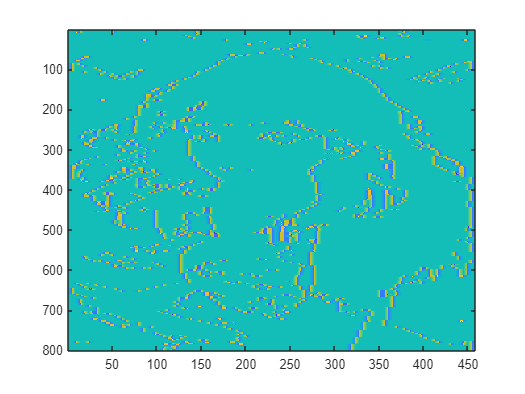


imwrite(res_1_cov, "p_4_cov.png")
imagesc(res_1_cov)



%====================================================================
% PART 2
%====================================================================

% find sizes of matrixes

[row, col] = size(w_s_im)

row = 800

col = 450


% image of wb picture
% block

main_im_1 = fft2(w_s_im, row + size(K, 1) - 1, col + size(K, 2) - 1)

main_im_1 = 1.0e+05 *

   1.9136 + 0.0000i  -0.4550 + 0.0730i  -0.0993 + 0.1654i  -0.0776 - 0.0961i  -0.0303 + 0.0508i  -0.0027 + 0.0345i  -0.0436 - 0.0057i  -0.0425 + 0.0080i  -0.0077 + 0.0093i  -0.0262 + 0.0063i  -0.0225 + 0.0105i  -0.0175 - 0.0020i  -0.0290 - 0.0070i  -0.0030 - 0.0028i  -0.0175 - 0.0161i  -0.0128 - 0.0130i  -0.0096 + 0.0085i  -0.0047 - 0.0294i   0.0008 - 0.0095i  -0.0107 - 0.0043i  -0.0019 - 0.0060i  -0.0128 - 0.0066i   0.0005 - 0.0114i   0.0004 - 0.0024i  -0.0061 - 0.0095i   0.0109 - 0.0079i   0.0085 - 0.0108i   0.0096 - 0.0029i  -0.0078 - 0.0047i   0.0077 - 0.0025i  -0.0006 + 0.0009i   0.0011 - 0.0017i   0.0052 - 0.0042i   0.0097 - 0.0103i   0.0010 - 0.0060i   0.0071 + 0.0009i  -0.0011 + 0.0016i   0.0024 - 0.0023i   0.0000 - 0.0014i   0.0038 - 0.0069i   0.0029 - 0.0006i   0.0050 - 0.0019i  -0.0037 + 0.0029i   0.0015 + 0.0005i   0.0062 - 0.0011i   0.0015 + 0.0004i   0.0007 + 0.0042i   0.0024 + 0.0005i   0.0046 + 0.0009i   0.0024 - 0.0006i
  -0.3060 + 0.0658i  -0.05

kern_im_1 = fft2(K, row + size(K, 1) - 1, col + size(K, 2) - 1)

kern_im_1 =    0.0000 + 0.0000i   0.0056 - 0.0003i   0.0224 - 0.0025i   0.0500 - 0.0083i   0.0879 - 0.0196i   0.1352 - 0.0381i   0.1911 - 0.0653i   0.2542 - 0.1027i   0.3232 - 0.1518i   0.3967 - 0.2136i   0.4729 - 0.2891i   0.5500 - 0.3792i   0.6261 - 0.4844i   0.6993 - 0.6052i   0.7674 - 0.7416i   0.8285 - 0.8935i   0.8804 - 1.0606i   0.9210 - 1.2424i   0.9485 - 1.4381i   0.9607 - 1.6465i   0.9558 - 1.8664i   0.9322 - 2.0964i   0.8883 - 2.3347i   0.8225 - 2.5795i   0.7337 - 2.8287i   0.6209 - 3.0801i   0.4832 - 3.3315i   0.3201 - 3.5803i   0.1312 - 3.8240i  -0.0836 - 4.0601i  -0.3240 - 4.2860i  -0.5897 - 4.4991i  -0.8799 - 4.6967i  -1.1937 - 4.8763i  -1.5298 - 5.0354i  -1.8868 - 5.1717i  -2.2630 - 5.2830i  -2.6563 - 5.3670i  -3.0646 - 5.4220i  -3.4856 - 5.4461i  -3.9168 - 5.4379i  -4.3554 - 5.3961i  -4.7986 - 5.3196i  -5.2435 - 5.2076i  -5.6870 - 5.0597i  -6.1261 - 4.8756i  -6.5577 - 4.6553i  -6.9786 - 4.3993i  -7.3858 - 4.1080i  -7.7761 - 3.7824i
   0.0000 - 0.0000i   0.0056 - 0.0003




% elements mult of matrixes

res_1 = ifft2(main_im_1 .* kern_im_1)

res_1 =    -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000 

norm_coef = max(res_1(:))

norm_coef = 8.0000

res_1 = res_1 / norm_coef

res_1 =    -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000 

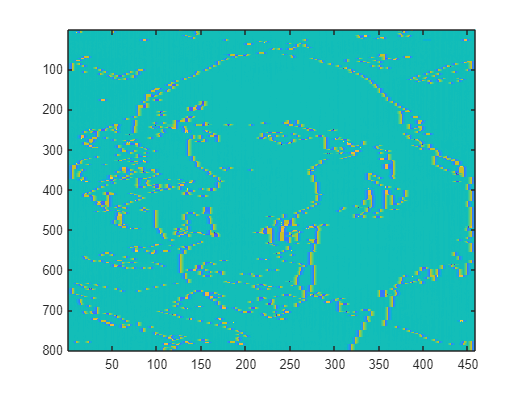


imwrite(res_1, "p_4_f.png")
imagesc(res_1)